[header1, seq1] = fastaread('/Users/aadithkrishna/Desktop/bio project/ratg.txt');
fprintf(seq1);

ATTAAAGGTTTATACCTTTCCAGGTAACAAACCAACGAACTCTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGACTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCATCTATCTTCTGCAGGTTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTCTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGCTTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGTGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCTGATGCTCGAACTGCACCTCATGGCCATGTTATGGTTGAGCTGGTAGCAGAACTTAATGGCATTCAGTATGGTCGTAGTGGTGAGACACTCGGTGTCCTTGTCCCTTATGTGGGCGAAACACCAGTGGTTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCTGATCTAAAGTCGTTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTCACCCGTGATCTCATGCGTGAGCTTAATGGAGGAGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCTCGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAAAGAGGTGTATACTGCTGTCGTGAACATGAGCATGAGATTGCTTGGTACACGGAACGTTCT

fprintf('The CGR matrix for SARS cov-2 genetic sequence');

The CGR matrix for SARS cov-2 genetic sequence

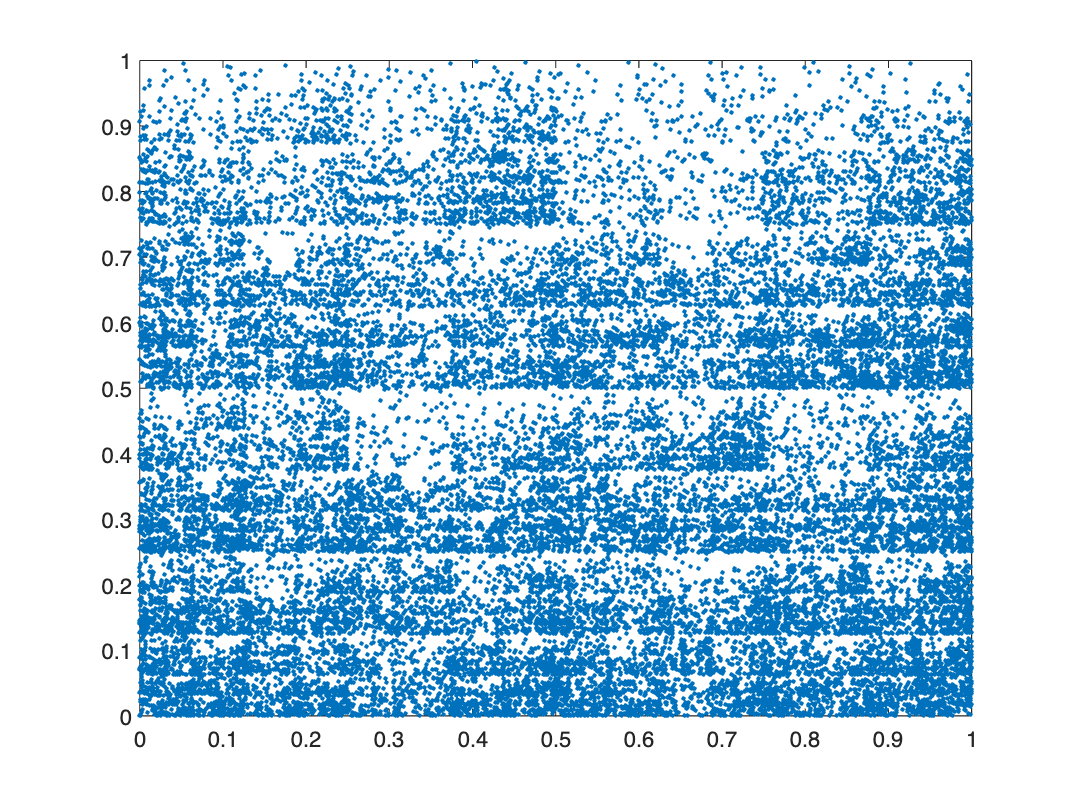

syms x1 y1 A G C T
    x0=0.5;
    y0=0.5;
    xa=0;
    xc=0;
    xg=1;
    xt=1;
    ya=0;
    yc=1;
    yt=0;
    yg=1;
    
    X0=[x0,y0];
    XA=[xa ya];
    XT=[xt yt];
    XC=[xc yc];
    XG=[xg yg];
    locx=[];
    locy=[];
    
    for i =1
      if r(1)==A
            x(i)=0.5*(xa+x0);
            y(i)=0.5*(ya+y0);
        elseif r(1)==T
            x(i)=0.5*(xt+x0);
             y(i)=0.5*(yt+y0);
        elseif r(1)==C
             x(i)=0.5*(xc+x0);
            y(i)=0.5*(yc+y0);
        else 
             x(i)=0.5*(xg+x0);
             y(i)=0.5*(yg+y0);
        end
        locx=[x(i) locx];
        locy=[y(i) locy];
    end
    for i=2:length(r)
        if r(i)==A
            x(i)=0.5*(xa+x(i-1));
            y(i)=0.5*(ya+y(i-1));
        elseif r(i)==T
             x(i)=0.5*(xt+x(i-1));
             y(i)=0.5*(yt+y(i-1));
        elseif r(i)==C
             x(i)=0.5*(xc+x(i-1));
             y(i)=0.5*(yc+y(i-1));
        else 
            x(i)=0.5*(xg+x(i-1));
             y(i)=0.5*(yg+y(i-1));
        end
         locx=[x(i) locx];
        locy=[y(i) locy];
    end
        
    %end
    
    plot(locx,locy,'.')



[s,sm] = findClumps(genome(1:1000),4,100,4);
kmers = sm(:,1);
ukmers = unique(kmers);
uukmers=[];
count =[];
for i =1 :length(ukmers)
count = [count ; (sum(kmers == ukmers(i)))];
uukmers =[uukmers ; ukmers(i)];
end
[freq,idx]= sort(count , 'descend');
top10 = ukmers(idx(1:10));
table(top10 , freq(1:10))

ans = 10×2 table
    top10     Var2
    ______    ____

    "ATTA"    172 
    "ACCA"    114 
    "ATGG"    114 
    "TCAA"    113 
    "AAAG"    107 
    "GAAC"     94 
    "CTCC"     83 
    "CACG"     79 
    "AGAT"     53 
    "GAAA"     51 


[header2, seq2] = fastaread('/Users/aadithkrishna/Desktop/bio project/beta_covid (2).txt');
fprintf(seq2);

ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACACGGAACGTTCT

fprintf('The CGR matrix for sample genetic sequence');

The CGR matrix for sample genetic sequence

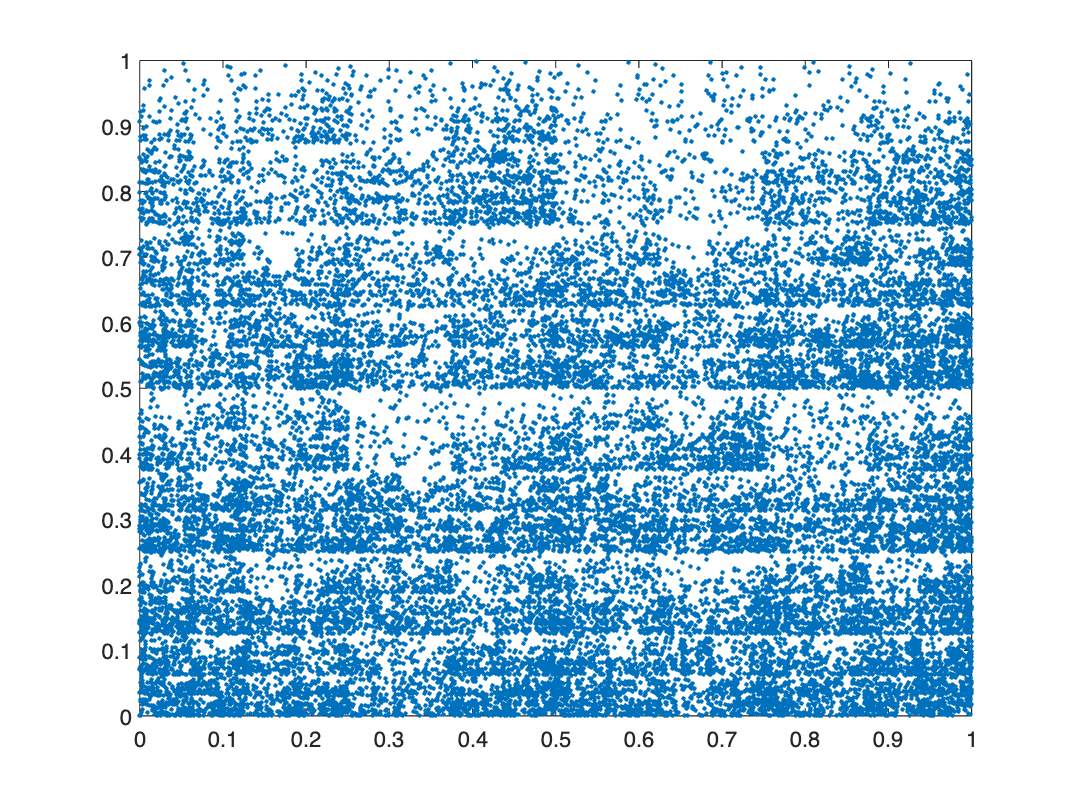

syms x1 y1 A G C T
    x0=0.5;
    y0=0.5;
    xa=0;
    xc=0;
    xg=1;
    xt=1;
    ya=0;
    yc=1;
    yt=0;
    yg=1;
    
    X0=[x0,y0];
    XA=[xa ya];
    XT=[xt yt];
    XC=[xc yc];
    XG=[xg yg];
    locx=[];
    locy=[];
    
    for i =1
      if r(1)==A
            x(i)=0.5*(xa+x0);
            y(i)=0.5*(ya+y0);
        elseif r(1)==T
            x(i)=0.5*(xt+x0);
             y(i)=0.5*(yt+y0);
        elseif r(1)==C
             x(i)=0.5*(xc+x0);
            y(i)=0.5*(yc+y0);
        else 
             x(i)=0.5*(xg+x0);
             y(i)=0.5*(yg+y0);
        end
        locx=[x(i) locx];
        locy=[y(i) locy];
    end
    for i=2:length(r)
        if r(i)==A
            x(i)=0.5*(xa+x(i-1));
            y(i)=0.5*(ya+y(i-1));
        elseif r(i)==T
             x(i)=0.5*(xt+x(i-1));
             y(i)=0.5*(yt+y(i-1));
        elseif r(i)==C
             x(i)=0.5*(xc+x(i-1));
             y(i)=0.5*(yc+y(i-1));
        else 
            x(i)=0.5*(xg+x(i-1));
             y(i)=0.5*(yg+y(i-1));
        end
         locx=[x(i) locx];
        locy=[y(i) locy];
    end
        
    %end
    
    plot(locx,locy,'.')


[s,sm] = findClumps(genome(1:1000),4,100,4);
kmers = sm(:,1);
ukmers = unique(kmers);
uukmers=[];
count =[];
for i =1 :length(ukmers)
count = [count ; (sum(kmers == ukmers(i)))];
uukmers =[uukmers ; ukmers(i)];
end
[freq,idx]= sort(count , 'descend');
top10 = ukmers(idx(1:10));
table(top10 , freq(1:10))

ans = 10×2 table
    top10     Var2
    ______    ____

    "ATTA"    172 
    "ACCA"    114 
    "ATGG"    114 
    "TCAA"    113 
    "AAAG"    107 
    "GAAC"     94 
    "CTCC"     83 
    "CACG"     79 
    "AGAT"     53 
    "GAAA"     51 




resolution = 100; 

cgrMatrix1 = generateCGRMatrix(seq1, resolution);
cgrMatrix2 = generateCGRMatrix(seq2, resolution);


figure;
subplot(1,2,1); imagesc(cgrMatrix1); title('CGR Matrix - Sequence 1'); colorbar;
subplot(1,2,2); imagesc(cgrMatrix2); title('CGR Matrix - Sequence 2'); colorbar;

similarity_percentage = compareCGR(cgrMatrix1, cgrMatrix2);

The similarity between the two CGR matrices is 90.91%.


function cgrplot = CGRplot(r)
    syms x1 y1 A G C T
    x0=0.5;
    y0=0.5;
    xa=0;
    xc=0;
    xg=1;
    xt=1;
    ya=0;
    yc=1;
    yt=0;
    yg=1;
    
    X0=[x0,y0];
    XA=[xa ya];
    XT=[xt yt];
    XC=[xc yc];
    XG=[xg yg];
    locx=[];
    locy=[];
    
    for i =1
      if r(1)==A
            x(i)=0.5*(xa+x0);
            y(i)=0.5*(ya+y0);
        elseif r(1)==T
            x(i)=0.5*(xt+x0);
             y(i)=0.5*(yt+y0);
        elseif r(1)==C
             x(i)=0.5*(xc+x0);
            y(i)=0.5*(yc+y0);
        else 
             x(i)=0.5*(xg+x0);
             y(i)=0.5*(yg+y0);
        end
        locx=[x(i) locx];
        locy=[y(i) locy];
    end
    for i=2:length(r)
        if r(i)==A
            x(i)=0.5*(xa+x(i-1));
            y(i)=0.5*(ya+y(i-1));
        elseif r(i)==T
             x(i)=0.5*(xt+x(i-1));
             y(i)=0.5*(yt+y(i-1));
        elseif r(i)==C
             x(i)=0.5*(xc+x(i-1));
             y(i)=0.5*(yc+y(i-1));
        else 
            x(i)=0.5*(xg+x(i-1));
             y(i)=0.5*(yg+y(i-1));
        end
         locx=[x(i) locx];
        locy=[y(i) locy];
    end
        
    
    plot(locx,locy,'.')
end
function cgrMatrix = generateCGRMatrix(sequence, resolution)
    coords = containers.Map({'A', 'T', 'C', 'G'}, {[0, 0], [1, 0], [0, 1], [1, 1]});
    
    cgrMatrix = zeros(resolution, resolution);
    
    x = 0.5;
    y = 0.5;
    
    for i = 1:length(sequence)
        if isKey(coords, sequence(i))
            corner = coords(sequence(i));
            x = (x + corner(1)) / 2;
            y = (y + corner(2)) / 2;
            
            row = min(resolution, max(1, ceil(x * resolution)));
            col = min(resolution, max(1, ceil(y * resolution)));
            
            cgrMatrix(row, col) = cgrMatrix(row, col) + 1;
        end
    end
end

function [clumpps,boxclumps] = findClumps(string, k , L , t)

clumps=[];
bclumps =[];

 for i=1:length(string)-L
start = i;
END = i+L-1;
box = string(start:END);
kmerpositions = kmerPositions(k,box);
kmers = kmerpositions.keys;
positions = kmerpositions.values;
for j=1:kmerpositions.Count
kmer = kmers{j};
poslist = positions{j};
for k_ = 1:length(poslist)
count = sum((poslist>=poslist(k_)) .* (poslist < poslist(k_)+L) );
if count>=t
Clump.kmer = kmer;
Clump.position = i;
Clump.count = count;
clumps = [clumps Clump];
bclumps = [bclumps ;convertCharsToStrings(kmer) i count];
end
end
end
end
clumpps = clumps;
boxclumps = bclumps;
end

function similarity = compareCGR(cgr1, cgr2)
    if size(cgr1) ~= size(cgr2)
        error('The two CGR matrices must have the same dimensions');
    end

    vec1 = cgr1(:);
    vec2 = cgr2(:);

    correlation = corr(vec1, vec2);

    similarity = correlation * 100;
    
    fprintf('The similarity between the two CGR matrices is %.2f%%.\n', similarity);
end

function [pp] = kmerPositions(k,seq)

kmerPosition = containers.Map;
for i=1:length(seq)-k+1
kmer = seq(i:i+k-1);

 if(kmerPosition.isKey(kmer))
kmerPosition(kmer) =sort( [kmerPosition(kmer) i] );
else
kmerPosition(kmer)=i;
end
end

keysss = kmerPosition.keys;
positions = kmerPosition.values;

pairPosition = containers.Map;
for i=1:kmerPosition.Count
kmer = keysss{i};
poslist = positions{i};

 temp=strrep(strrep(strrep(strrep( kmer(end:-1:1) ,'A','*'),'C','.'),'T','A'),'G','C');
krev = strrep(strrep(temp,'*','T'),'.','G');

 if( convertCharsToStrings(kmer) < convertCharsToStrings(krev))
if(kmerPosition.isKey(krev))
pairPosition(kmer) = sort([poslist, kmerPosition(krev)] );
else
pairPosition(krev) = sort(poslist);
end
elseif(convertCharsToStrings(krev) < convertCharsToStrings(kmer))
if(kmerPosition.isKey(krev))
pairPosition(krev) = sort([kmerPosition(krev),poslist]);
else
pairPosition(krev) = sort(poslist);
end
else
pairPosition(kmer)=poslist;
end
pp = pairPosition;

end

end
